# Processing Data Samples from MRI

## Data Collection

Library is already loaded.

Functions in library libModuleConnector64:

data_reader_at_end                    nva_read_message_presence_single      
data_reader_close                     nva_read_x4_spi                       
data_reader_create                    nva_reset                             
data_reader_destroy                   nva_run_timing_measurement            
data_reader_get_data_types            nva_send_command                      
data_reader_get_duration              nva_send_command_single               
data_reader_get_filter                nva_set_X2_float                      
data_reader_get_max_record_size       nva_set_X2_int                        
data_reader_get_session_id            nva_set_X2_register                   
data_reader_get_size                  nva_set_basename_for_data_type        
data_reader_get_start_epoch           nva_set_debug_level                   
data_reader_is_open                   nva_set_detection_zone                
data

Read 90 frames. A total of 90 were sent from chip. Frames dropped: 0
Estimated FPS: 89.2677, should be: 90
Closing radar


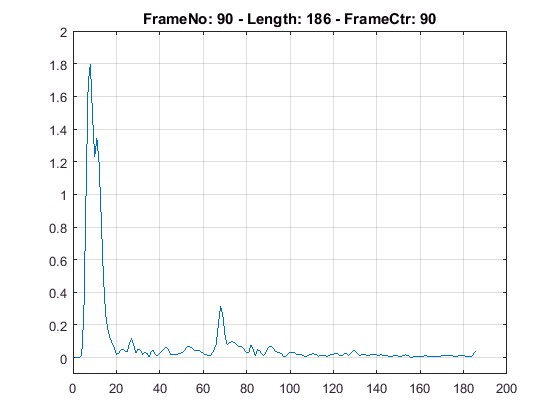

Fs = 90.0;
Duration = 1.0; % Seconds
raw_sample = acquire_radar_data(Fs, Duration);

Drawing the Raw Data

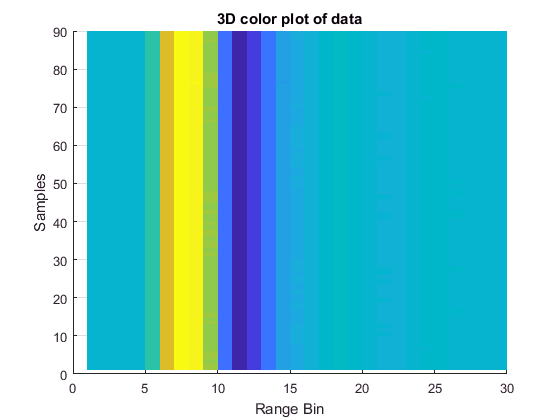

Fs = 60.0;
Duration = 30.0; % Seconds

figure(1);
raw_chest_sample_real = real(raw_sample);
surf(raw_chest_sample_real(1:end, 1:30), 'EdgeColor', 'None');
title('3D color plot of data');
view(2);
xlabel('Range Bin')
ylabel('Samples')

figure(2);

Zeroing out data

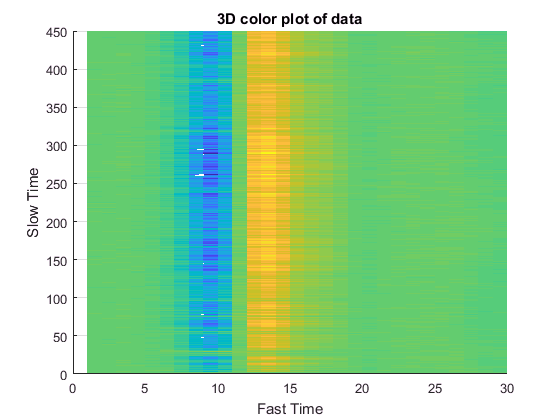

[slowTime, fastTime] = size(raw_sample);
sample = zeros(slowTime, fastTime);
zero_sample = raw_sample(1,:);
for i=1:slowTime
    sample(i,:) = raw_sample(i,:) - zero_sample;
end
sample_real = real(sample);
surf(sample_real(1:end, 1:30), 'EdgeColor', 'None');
title('3D color plot of data');
xlabel('Fast Time')
ylabel('Slow Time')
view(2);


clear i zero_sample;